**The simulations of the modified model where Y also shuttles. **

**For Figure S3b.**

% Basic paramters
load ../Parameter_determination/Basic_parameters.mat

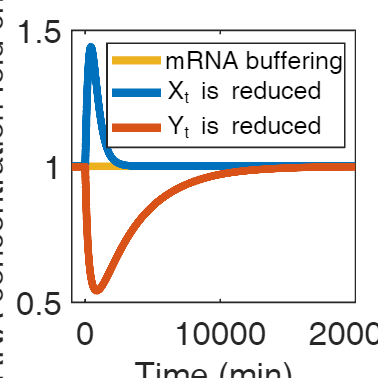

para0=para_opt;

% Modify the paramters
para0(5)=para_opt(5)*20;

k0=para0(1);
am=para0(5);
ax=para0(6);
ay=para0(7);
bx=para0(9);
bm=para0(8);
Kx=para0(2);
Km=para0(4);
Vn=2.8;
Vc=37.2;
Ky=para0(3);
Xt=para0(10);
Yt=para0(11);
Kv=5.8262;
by=para0(9);

para1=[para0,Vn,Vc,Kv,by];

% Initialization
mn0=2.23e3;
mc0=8.41e3;
Xn0=5e3;
Xc0=224730;
Xp0=270;
Yn0=964;
Yp0=10036;
Yc0=Yn0;
y_ini=[mn0,mc0,Xn0,Xc0,Xp0,Yn0,Yp0,Yc0];


% Calculate the homeostatic values
tspan=[1:1:1e4];
[~,y_tot]=ode15s(@(t,y)diffun(y,para1),tspan,y_ini);
y_ini2=y_tot(end,:);


%%% Depletion of Y
y_ini3=y_ini2;
y_ini3(6)=y_ini2(6)/10;
y_ini3(7)=y_ini2(7)/10;
y_ini3(8)=y_ini2(8)/10;

tspan=[1:1:2e4];
[~,y_tot2]=ode15s(@(t,y)diffun(y,para1),tspan,y_ini3);

y_all_Y=[y_tot(end-1e3:end,:);y_tot2(1:2e4,:)];

mn=y_all_Y(:,1);
mc=y_all_Y(:,2);
m_all_Y=mn+mc;


%%% Depletion of X
y_ini3=y_ini2;
y_ini3(3)=y_ini2(3)/10;
y_ini3(4)=y_ini2(4)/10;
y_ini3(5)=y_ini2(5)/10;

tspan=[1:1:2e4];
[~,y_tot3]=ode15s(@(t,y)diffun(y,para1),tspan,y_ini3);

y_all_X=[y_tot(end-1e3:end,:);y_tot3(1:2e4,:)];

mn=y_all_X(:,1);
mc=y_all_X(:,2);
m_all_X=mn+mc;


% Plot
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];


fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);


scale_time=(1:length(m_all_X))-1e3;
p1=plot(scale_time,ones(1,length(m_all_X)),'-', ...
    "LineWidth",5, ...
    "Color",colors(3),...
    "DisplayName","mRNA buffering");
hold on
p2=plot(scale_time,m_all_X/m_all_X(1)+0.001,'-', ...
    "LineWidth",5, ...
    "Color",colors(1),...
    "DisplayName","X_t is reduced");
hold on
p3=plot(scale_time,m_all_Y/m_all_Y(1)-0.001,'-', ...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","Y_t is reduced");
hold off
xlim([-1e3,2e4])

set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2 p3],"Interpreter","tex","FontSize",15)
xlabel('Time (min)','interpreter','tex','FontSize',20);
ylabel('mRNA concentration fold change','interpreter','tex','FontSize',20);

function dydt = diffun(y,para)
%%% Differential equations of the system

%y:[mn mc Xn Xc Xp Yn Yp Yc]
mn=y(1);
mc=y(2);
Xn=y(3);
Xc=y(4);
Xp=y(5);
Yn=y(6);
Yp=y(7);
Yc=y(8);


%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv by]

k0=para(1);
Kx=para(2);
Ky=para(3);
Km=para(4);
am=para(5);
ax=para(6);
ay=para(7);
bm=para(8);
bx=para(9);
%Xt=para(10);
%Yt=para(11);
Vn=para(12);
Vc=para(13);
Kv=para(14);
by=para(15);


dydt = zeros(8,1);
%dydt:[dmndt dmcdt dXndt dXcdt dXpdt dYndt dYpdt dPndt dPnbdt dPcdt dPcbdt]


kn=(k0*Vn/(Vn+Kv))*...
    (Xp/(Xp+Kx*Vn))*...
    Vn*Km/(Vn*Km+mn)*...
    Yp/(Yp+Ky*Vn);


dydt(1)=kn-am*(Yn/Vn)*mn;
dydt(2)=am*(Yn/Vn)*mn-bm*(Xc/Vc)*mc;
dydt(3)=kn-ax*Xn;
dydt(4)=ax*Xn-bx*Xc;
dydt(5)=bx*Xc-kn;
dydt(6)=kn-ay*Yn;
dydt(7)=by*Yc-kn;
dydt(8)=ay*Yn-by*Yc;


end

